## Problem 3 (30 points)

## Problem 3.1 

Simulate N := $10^4
$ independent random walkers (as discussed in class) along the real line, each walker starting at the origin, and each walker taking $10^3

$ steps each of length$10^{-3}
$.

% standard notations as used in slides
N = 10^4;
p = 0.5;
q = 1-p;
n = 10^3;
dz = 10^(-3);

### Part 1 [5 points]

Plot a histogram of the final locations of all the random walkers. You may use the hist(.) function in Matlab.

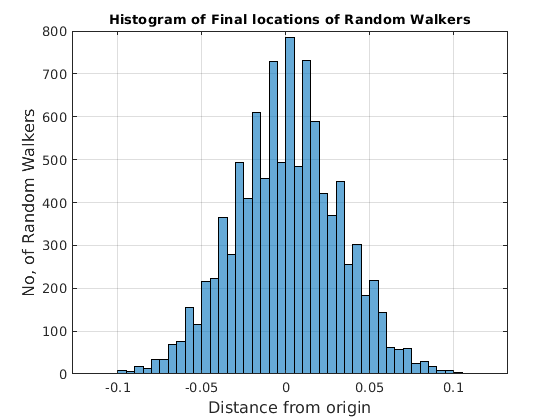

rng(1);
x = binornd(n,p,1,N); % 1 x N matrix representing number of right steps taken by N random walkers in n trials
final_locations = (2*x-n)*dz; % 1 x N matrix containing final_location of N random walkers

histogram(final_locations)
grid on;
ylabel('No, of Random Walkers', 'FontSize', 12);
xlabel('Distance from origin', 'FontSize', 12);
title('Histogram of Final locations of Random Walkers', 'FontSize', 10);

### Part 2 [5 points]

For the first $10^3
$ walkers, plot space-time curves that show the path taken by each walker (as depicted in the class slides). On the graph, draw each path in a different randomly-chosen color for better clarity.

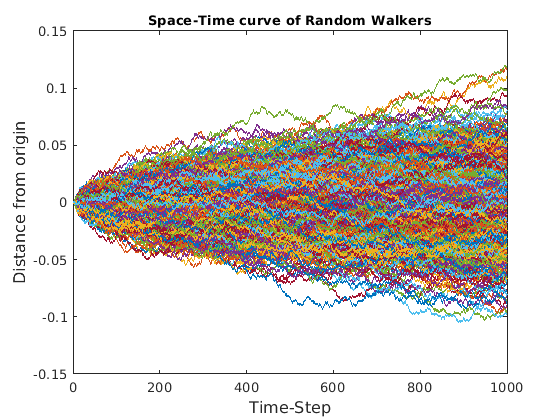

rng(2)
Ns = N/10; % Ns is new No. of random walker specified for this part of the problem

z = zeros(n,Ns); % n x Ns matrix to contain location of each Ns random walker after each step 1,2,3....n
for i = 1:Ns-1  
    % every row is obtained by adding to the previous row 1 or -1 depending
    % on whether the ith step was right or left.
    z(i+1,:) = z(i,:) + 2*(rand(1,Ns)>p)-1; % 2*(rand(1,Ns)>p)-1 is 1 x Ns matrix which contains 1/-1 for right/left step
end
z = z*dz; % scaling

plot(z(:,1:end))
ylabel('Distance from origin', 'FontSize', 12);
xlabel('Time-Step', 'FontSize', 12);
title('Space-Time curve of Random Walkers', 'FontSize', 10);

### Problem 3.2

Consider a random variable X . Consider a dataset that comprises N independent draws (e.g., modeled by $X_1$ , · · · , $X_N
$ ) from the distribution of X . Use the law of large numbers to show that the random variable $\hat M := (X_1+\dots + X_N)/N$ converges to the true mean M := E[X] as N → ∞ .

Prove that the expected value of the random variable $\hat V:= \sum_{i=1}^N (X_i - \hat M)^2/N$ tends to the true variance V := Var (X) as N → ∞ . It can also be shown that the variance of the random variable $\hat V$ tends to zero as N → ∞ ; the proof is a bit tedious though (see https://mathworld.wolfram.com/SampleVarianceDistribution.html ).

### Part 3

Report the empirically-computed mean $\hat M$and the empirically-computed variance $\hat V
$of the locations of the random walkers.

empirical_mean = sum(final_locations)/N

empirical_mean = 3.9120e-04

empirical_variance = sum((final_locations-empirical_mean).^2)/N

empirical_variance = 9.9757e-04

### Part 4

What should the values of the true mean and the true variance be for the random variable that models the location of the random walker, as function of the step length and the number of steps ?

mean_x = n*p; % mean of a binomial distribution
variance_x = n*p*q; % variance of a binomial distribution

true_mean = (2*mean_x-n)*dz % theoritical mean

true_mean = 0

true_variance = (2)^2*variance_x*(dz)^2 % theoritical variance

true_variance = 1.0000e-03

### Part 5

Report the error between the empirically-computed mean and the true mean.

Report the error between the empirically-computed variance and the true variance.

error_mean = abs(true_mean-empirical_mean)

error_mean = 3.9120e-04

error_variance = abs(true_variance-empirical_variance)

error_variance = 2.4314e-06